# Demo 1: RepViT Image Classification

Load a RepViT PyTorch ExportedProgram and classify an image.

## Load and Display a Test Image

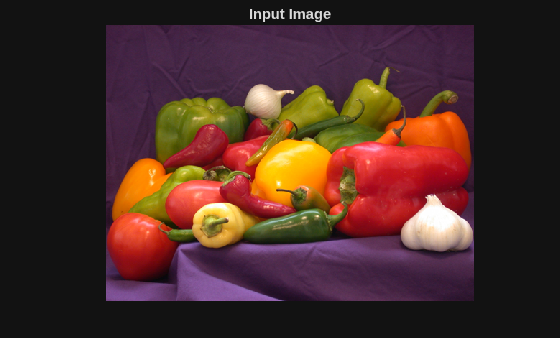

img = imread("peppers.png");
imshow(img);
title("Input Image");

## Run Inference

scores = repvit_predict(img);

W0406 09:50:30.125000 1419709 torch/export/pt2_archive/_package.py:846] You are loading weight from the legacy format. Please generate a new pt2 file using torch.export.save().
W0406 09:50:30.875000 1419709 torch/export/pt2_archive/_package.py:900] You are loading constant from the legacy format. Please generate a new pt2 file using torch.export.save().

Loading the model. This may take a few minutes.


## Display Top-5 Predictions

classNames = readlines("imagenet_classes.txt");
[sorted_scores, idx] = sort(scores, 'descend');
fprintf('\nTop-5 Predictions:\n');


Top-5 Predictions:


for i = 1:5
    fprintf('  %s: %.4f\n', classNames(idx(i)), sorted_scores(i));
end

  bell pepper: 10.8388
  cucumber, cuke: 5.4397
  grocery store, grocery, food market, market: 4.5443
  Granny Smith: 3.9857
  spaghetti squash: 3.6904


## Generate MEX (Code Generation)

cfg = coder.config("mex");
codegen repvit_predict -config cfg -args {img};

W0406 09:52:46.078000 1419709 torch/export/pt2_archive/_package.py:846] You are loading weight from the legacy format. Please generate a new pt2 file using torch.export.save().
W0406 09:52:46.099000 1419709 torch/export/pt2_archive/_package.py:900] You are loading constant from the legacy format. Please generate a new pt2 file using torch.export.save().
Code generation successful.



fprintf('MEX function generated successfully.\n');

MEX function generated successfully.


## Run Generated MEX

scores_mex = repvit_predict_mex(img);
[~, pred_mex] = max(scores_mex);
[~, pred_ml] = max(scores);
fprintf('MATLAB prediction: class %d\n', pred_ml);

MATLAB prediction: class 946


fprintf('MEX prediction:    class %d\n', pred_mex);

MEX prediction:    class 946


fprintf('Match: %s\n', string(pred_ml == pred_mex));

Match: true
